# Robotics II

Midterm April 26 2018

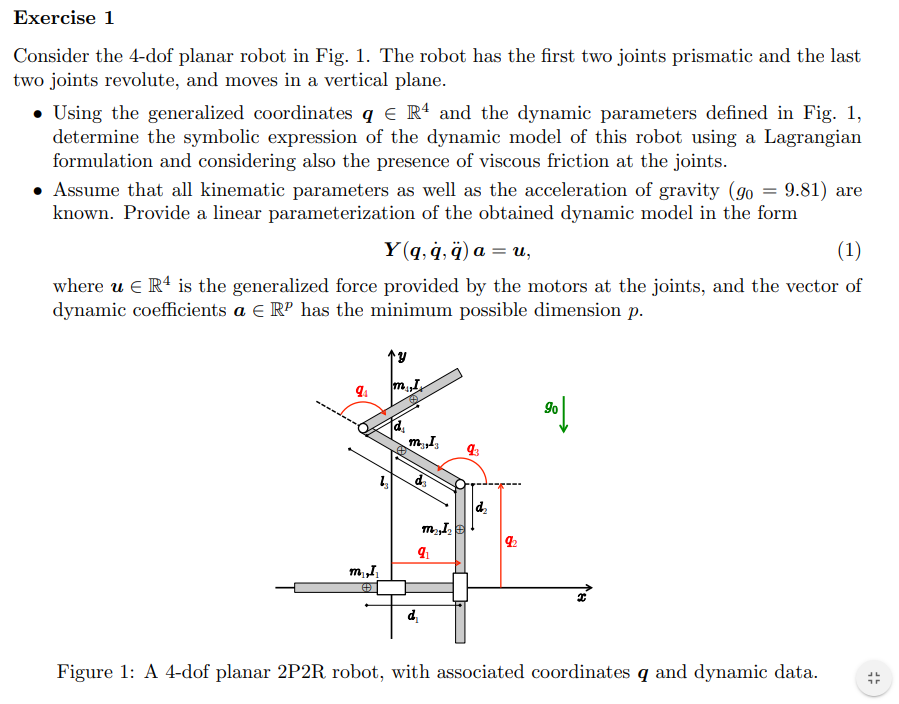

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1,0,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% 
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% isMotor=0;

% % %Insert manually the global positions of the centers of mass
% % pc(:,1) = [q(1) 0];
% % pc(:,2) = [q(1)+k(1)+dc(2)*cos(q(2)), dc(2)*sin(q(2))];
% % pc(:,3) = [q(1)+k(1)+l(2)*cos(q(2))+dc(3)*cos(q(2)+q(3)), l(2)*sin(q(2))+dc(3)*sin(q(2)+q(3))]
% % [pct,qt]=ToTimedep(pc,n,'t','q')
% % vct = diff(pct,t)
% % [vc,q_d1,vc_short]=shortdiff(vct,sym2cell(qt),t,true,1,qd)%,[qd,qdd])
% % w =[0, qd(2), qd(2)].';
% % % for i=1:n
% % %  T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
% % % end
% % % KE = sum(T.')
% % % 
% % 

%  
% R2Robot=['pprr';'xyxx';[1,1,1,1]]       

% [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I)
% 

## minimal parametrization

%  [C,cac,Csubs,S] = getCs(M,q,qd);
%  [Msubs, dynamicParameters, a] = getDynamicParameters(M,q,l',2)%l')
%  [Csubs,cacsubs,Csubssubs,Ssubs] = getCs(Msubs,q,qd)
% 

## manual minimization

% % Msubs_2=subs(Msubs,a(7),dynamicParameters(7))
% % dynamicParameters
% % unique(Msubs_2(find(has(Msubs_2,dynamicParameters(7))) ))
% %  
% 

## gratvity computing

%  %viscous_Friction====>fv;
% [g_q, PE, U,g_q_short,PE_short,fv] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor);
%  [g_qsubs, dynamicParametersG, aG] = getDynamicParameters(g_q(1:end),q,[g0],2)
%  [g_qsubs_,dynamicParameters,a] = matchingFuncs(g_qsubs,dynamicParameters,dynamicParametersG,a,aG);
%  
%  dynamicParameters_=[dynamicParameters;fv]
%  au=sym('a',[10,1],'real')
%  u_subs=Msubs*qdd+cacsubs+g_qsubs_+au(7:end).*qd
%   [Yu, Yushort] = getLinearParametrization(u_subs,au)
% simplify(u_subs-Yu*au)


## exercise 2

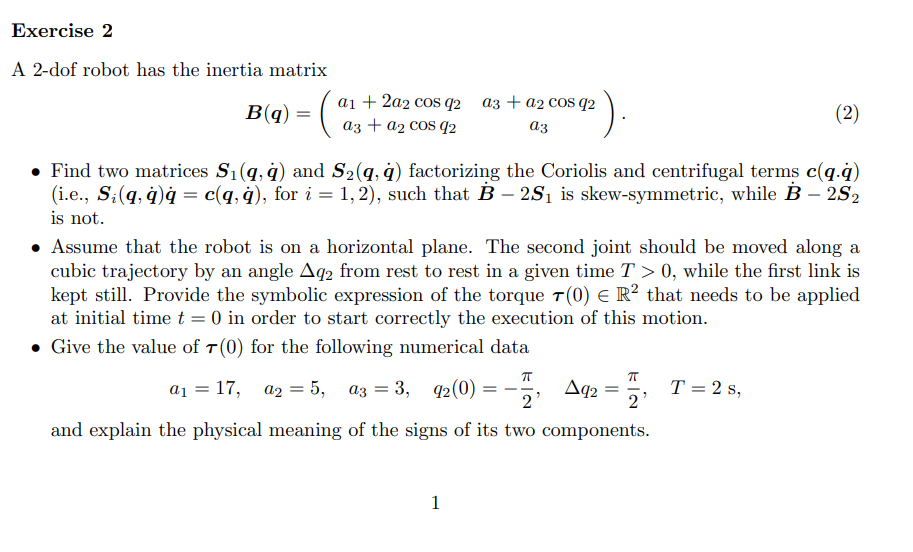

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q0 = sym('q0', [n 1],'real');
% qf = sym('qf', [n 1],'real');
% 
% a = sym('a', [3 1],'real');
% T = sym('T', [1 1],'real');
% t_ = sym('t_','real');
% 
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% qdd0 = sym('qdd0', [n 1],'real'); 
% 
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% isMotor=0;

% % %Insert manually the global positions of the centers of mass
% % pc(:,1) = [q(1) 0];
% % pc(:,2) = [q(1)+k(1)+dc(2)*cos(q(2)), dc(2)*sin(q(2))];
% % pc(:,3) = [q(1)+k(1)+l(2)*cos(q(2))+dc(3)*cos(q(2)+q(3)), l(2)*sin(q(2))+dc(3)*sin(q(2)+q(3))]
% % [pct,qt]=ToTimedep(pc,n,'t','q')
% % vct = diff(pct,t)
% % [vc,q_d1,vc_short]=shortdiff(vct,sym2cell(qt),t,true,1,qd)%,[qd,qdd])
% % w =[0, qd(2), qd(2)].';
% % % for i=1:n
% % %  T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
% % % end
% % % KE = sum(T.')
% % % 
% % 

%  
% % R2Robot=['pr';'yx';[1,1]]    
% Msubs=[a(1)+2*a(2)*cos(q(2)),a(3)+a(2)*cos(q(2));
%         a(3)+a(2)*cos(q(2)),a(3)
%         ]

% [Csubs,cacsubs,Csubssubs,S1] = getCs(Msubs,q,qd)
% svals=[a(2)*sin(q(2))*qd(1),0]';%% possible solution
% % svals=[qd(1),0]';%% possible solution also works
% 
% [S0_,S_,S0v] = getGenericS0(q,qd,svals);
% S2=simplify(S1+S0v{1})

## checking symmetry

% [Msubsd,Mtsubsd,qt] = getM_dot(Msubs,q,qd)
% Msubsd-2*S1
% Msubsd-2*S2
% 

## cubic splitline

% [spline_fun,Aw_fun,Aa_fun,Ajerk_fun,MaxsVal] = splinesD(2,1,[0 T],[q0(2) qf(2)],3,false)
% qdd20_=simplify(expand(subs(Aa_fun,t_,0)))
% qdd202_=simplify(expand(subs(qdd20_,[q0(2),qf(2),T(1)],[-pi/2,0,2])))
% 

## the gravity only affects vertically for this reason doesn't appear

% tao=Msubs*qdd+cacsubs
% tao0_=simplify(subs(tao,[qd;qdd],[0;0;0;qdd0(2)]))
% a_=[17,5,3];
% tao02_=vpa(subs(tao0_,[a',q(2),qdd0(2)],[a_,-pi/2,qdd202_]))


## exercise 3

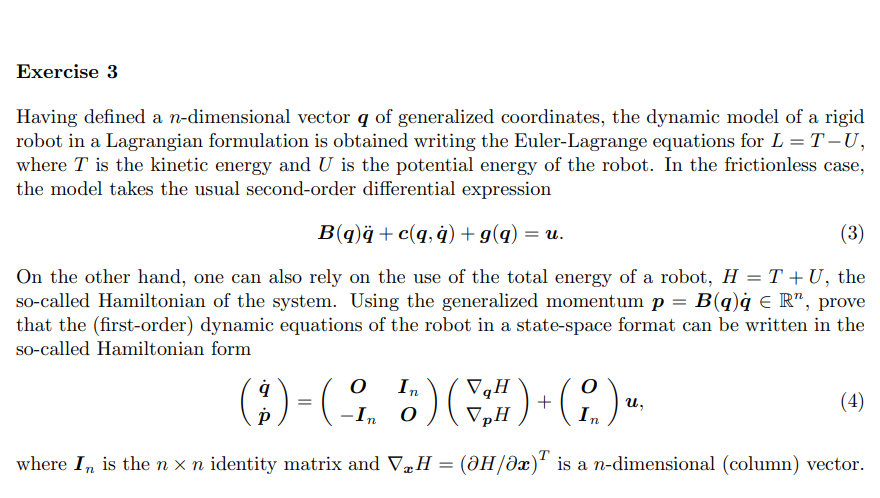

Ver examen ahha it is just a demostration

## Exercise 4

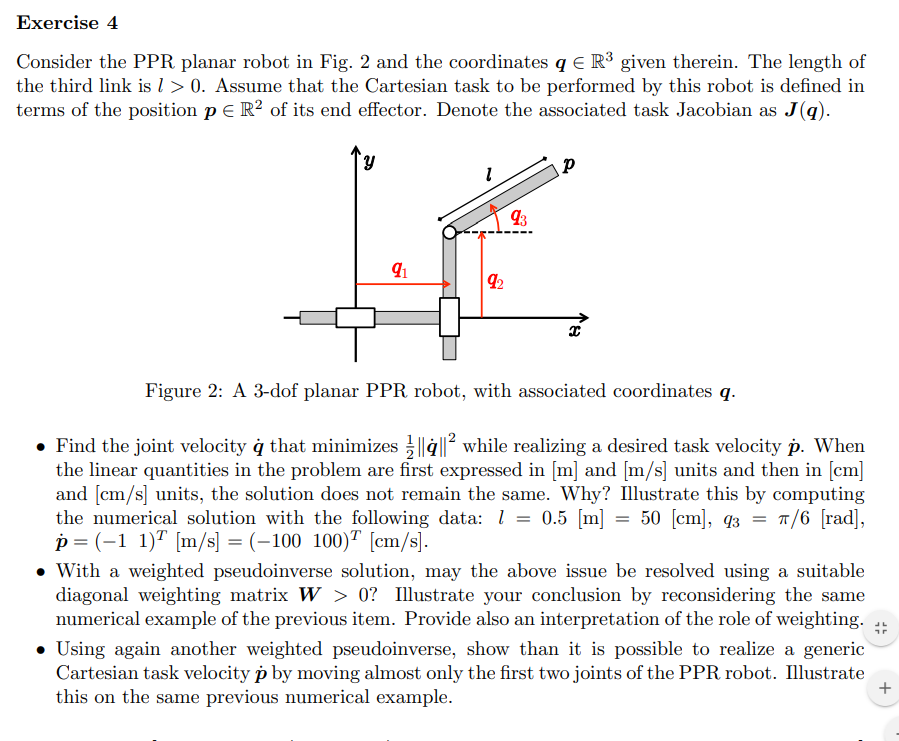

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,1,0];
n = length(sigma);
t = sym('t', 'real');
q = sym('q', [n 1],'real');
qd = sym('qd', [n 1],'real');
pd = sym('pd', [2 1],'real');

qdd = sym('qdd', [n 1],'real'); 

dc = sym('dc', [n 1],'real');
k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');

m = sym('m', [n 1],'real');
I = sym('I', [n 1],'real');
g0 = sym('g0','real');
g=[0,-g0,0]';
isMotor=0;

%  
lmeters_=[0.5,0.5,0.5]'

lmeters_ =     0.5000
    0.5000
    0.5000


q_=[q(1),q(2),pi/6]'

$$q\_ = \left(\begin{array}{c} q_{1}\\ q_{2}\\ \frac{\pi }{6} \end{array}\right)$$

pdotmeters_=[-1,1]'

pdotmeters_ =     -1
     1



lcm_=[50,50,50]'

lcm_ =     50
    50
    50


pdotcm_=[-100,100]'

pdotcm_ =   -100
   100



varsreplace=[l;q;pd];
varsreplacemeters_=[lmeters_;q_;pdotmeters_];
varsreplacecm_=[lcm_;q_;pdotcm_];
R2Robot=['ppr';'xyx';[1,1,1]]       

R2Robot = 3×3 char array
    'ppr'
    'xyx'
    ''


% [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I)
% % 
% J=jacobian(Pc(:,end),q)
xyonly=true;
[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot] = getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)

si falla aquí está el error


$$f = \left(\begin{array}{c} q_{1}+l_{3}\,\cos\left(q_{3}\right)\\ q_{2}+l_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

$$J = \left(\begin{array}{ccc} 1 & 0 & -l_{3}\,\sin\left(q_{3}\right)\\ 0 & 1 & l_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$

$$V = \left(\begin{array}{c} {\mathrm{qd}}_{1}-l_{3}\,{\mathrm{qd}}_{3}\,\sin\left(q_{3}\right)\\ {\mathrm{qd}}_{2}+l_{3}\,{\mathrm{qd}}_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$

$$J\_ps = \begin{array}{l} \left(\begin{array}{cc} \frac{-{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+{l_{3}}^{2}+1}{{l_{3}}^{2}+1} & \sigma_{1}\\ \sigma_{1} & \frac{{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+1}{{l_{3}}^{2}+1}\\ -\frac{l_{3}\,\sin\left(q_{3}\right)}{{l_{3}}^{2}+1} & \frac{l_{3}\,\cos\left(q_{3}\right)}{{l_{3}}^{2}+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{l_{3}}^{2}\,\sin\left(2\,q_{3}\right)}{2\,\left({l_{3}}^{2}+1\right)} \end{array}$$

PCVar = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: [1×1 sym]
    Ti: [1×3 sym]
     M: [3×3 sym]


PC_EEShort = struct with fields:
    f: [2×1 sym]
    J: [2×3 sym]
    V: [2×1 sym]


VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: [1×1 sym]
    Ti: [1×3 sym]
     M: [3×3 sym]


% J_ps=subs()

## the simples way for minimize q dot is

x_dot=[2,1]'

x_dot =      2
     1


J=[3,1,2;1.5,0.5,1]

J =     3.0000    1.0000    2.0000
    1.5000    0.5000    1.0000


rank(J)

ans = 1

J_ps=pinv(J)

J_ps =     0.1714    0.0857
    0.0571    0.0286
    0.1143    0.0571


q_dot_star=J_ps*x_dot

q_dot_star =     0.4286
    0.1429
    0.2857


norm(q_dot_star)

ans = 0.5345

W=eye(3)

w_ =      1     0     0
     0     1     0
     0     0     1


W(1,1)=20
% w_(1,1)=0

w_ =      0     0     0
     0     1     0
     0     0     1


% w_=0.5*q_dot_star'*w_*q_dot_star
qdotstar=q_dot_star+pinv(J*W)*(x_dot-J*q_dot_star)
norm(qdotstar)

% [qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)

[J_pseudo_w,J__pseudo,W] = WeightedPseInverse(W,J,q,[])
q_dot_star2=J_pseudo_w*x_dot
norm(q_dot_star2)
% 
% qd_min=J_ps*pd
% digits(4)
% %meters
% qd_minmeters_=vpa(subs(qd_min,varsreplace,varsreplacemeters_))
% 
% %cm
% qd_mincm_=vpa(subs(qd_min,varsreplace,varsreplacecm_))


## weighted pseudo inverse

[J_pseudo_w,J__pseudo,W,Wvars] = WeightedPseInverse([],J,q,[1,1,0])

W must be negative, pay attention


$$W = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & W_{3,3} \end{array}\right)$$

$$J\_pseudo\_w = \begin{array}{l} \left(\begin{array}{cc} \frac{-{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+{l_{3}}^{2}+W_{3,3}}{{l_{3}}^{2}+W_{3,3}} & \sigma_{1}\\ \sigma_{1} & \frac{{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+W_{3,3}}{{l_{3}}^{2}+W_{3,3}}\\ -\frac{l_{3}\,\sin\left(q_{3}\right)}{{l_{3}}^{2}+W_{3,3}} & \frac{l_{3}\,\cos\left(q_{3}\right)}{{l_{3}}^{2}+W_{3,3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{l_{3}}^{2}\,\sin\left(2\,q_{3}\right)}{2\,\left({l_{3}}^{2}+W_{3,3}\right)} \end{array}$$

$$J\_\_pseudo = \begin{array}{l} \left(\begin{array}{cc} \frac{-{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+{l_{3}}^{2}+1}{{l_{3}}^{2}+1} & \sigma_{1}\\ \sigma_{1} & \frac{{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+1}{{l_{3}}^{2}+1}\\ -\frac{l_{3}\,\sin\left(q_{3}\right)}{{l_{3}}^{2}+1} & \frac{l_{3}\,\cos\left(q_{3}\right)}{{l_{3}}^{2}+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{l_{3}}^{2}\,\sin\left(2\,q_{3}\right)}{2\,\left({l_{3}}^{2}+1\right)} \end{array}$$

$$W = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & W_{3,3} \end{array}\right)$$

$$Wvars = W_{3,3}$$


J_pseudo_w_=subs(J_pseudo_w,Wvars,l(3)^2)

$$J\_pseudo\_w\_ = \left(\begin{array}{cc} -\frac{{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}-2\,{l_{3}}^{2}}{2\,{l_{3}}^{2}} & \frac{\sin\left(2\,q_{3}\right)}{4}\\ \frac{\sin\left(2\,q_{3}\right)}{4} & \frac{{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+{l_{3}}^{2}}{2\,{l_{3}}^{2}}\\ -\frac{\sin\left(q_{3}\right)}{2\,l_{3}} & \frac{\cos\left(q_{3}\right)}{2\,l_{3}} \end{array}\right)$$


qd_minW=J_pseudo_w_*pd

$$qd\_minW = \begin{array}{l} \left(\begin{array}{c} \frac{{\mathrm{pd}}_{2}\,\sin\left(2\,q_{3}\right)}{4}-\frac{{\mathrm{pd}}_{1}\,\left(\sigma_{1}-2\,{l_{3}}^{2}\right)}{2\,{l_{3}}^{2}}\\ \frac{{\mathrm{pd}}_{1}\,\sin\left(2\,q_{3}\right)}{4}+\frac{{\mathrm{pd}}_{2}\,\left(\sigma_{1}+{l_{3}}^{2}\right)}{2\,{l_{3}}^{2}}\\ \frac{{\mathrm{pd}}_{2}\,\cos\left(q_{3}\right)}{2\,l_{3}}-\frac{{\mathrm{pd}}_{1}\,\sin\left(q_{3}\right)}{2\,l_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2} \end{array}$$

digits(4)
%meters
qd_minmeters_=vpa(subs(qd_minW,varsreplace,varsreplacemeters_)) %m/s

$$qd\_minmeters\_ = \left(\begin{array}{c} -0.6585\\ 0.4085\\ 1.366 \end{array}\right)$$


%cm
qd_mincm_=vpa(subs(qd_minW,varsreplace,varsreplacecm_)) %cm/s

$$qd\_mincm\_ = \left(\begin{array}{c} -65.85\\ 40.85\\ 1.366 \end{array}\right)$$


J_pseudo_w_=subs(J_pseudo_w,Wvars,1000)

$$J\_pseudo\_w\_ = \begin{array}{l} \left(\begin{array}{cc} \frac{-{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+{l_{3}}^{2}+1000}{{l_{3}}^{2}+1000} & \sigma_{1}\\ \sigma_{1} & \frac{{l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}+1000}{{l_{3}}^{2}+1000}\\ -\frac{l_{3}\,\sin\left(q_{3}\right)}{{l_{3}}^{2}+1000} & \frac{l_{3}\,\cos\left(q_{3}\right)}{{l_{3}}^{2}+1000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{l_{3}}^{2}\,\sin\left(2\,q_{3}\right)}{2\,\left({l_{3}}^{2}+1000\right)} \end{array}$$


qd_minW=J_pseudo_w_*pd

$$qd\_minW = \begin{array}{l} \left(\begin{array}{c} \frac{{\mathrm{pd}}_{1}\,\left(-\sigma_{1}+{l_{3}}^{2}+1000\right)}{{l_{3}}^{2}+1000}+\frac{{l_{3}}^{2}\,{\mathrm{pd}}_{2}\,\sin\left(2\,q_{3}\right)}{\sigma_{2}}\\ \frac{{\mathrm{pd}}_{2}\,\left(\sigma_{1}+1000\right)}{{l_{3}}^{2}+1000}+\frac{{l_{3}}^{2}\,{\mathrm{pd}}_{1}\,\sin\left(2\,q_{3}\right)}{\sigma_{2}}\\ \frac{l_{3}\,{\mathrm{pd}}_{2}\,\cos\left(q_{3}\right)}{{l_{3}}^{2}+1000}-\frac{l_{3}\,{\mathrm{pd}}_{1}\,\sin\left(q_{3}\right)}{{l_{3}}^{2}+1000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={l_{3}}^{2}\,{\sin\left(q_{3}\right)}^{2}\\ \sigma_{2}=2\,\left({l_{3}}^{2}+1000\right) \end{array}$$

digits(4)
%meters
qd_minmeters_=vpa(subs(qd_minW,varsreplace,varsreplacemeters_)) %m/s

$$qd\_minmeters\_ = \left(\begin{array}{c} -0.9998\\ 0.9997\\ 0.0006828 \end{array}\right)$$


%cm
qd_mincm_=vpa(subs(qd_minW,varsreplace,varsreplacecm_)) %cm/s

$$qd\_mincm\_ = \left(\begin{array}{c} -51.21\\ 15.5\\ 1.951 \end{array}\right)$$